# FFT - easy with Live Editor

Fs = 50000;     % Sampling frequency
T = 1/Fs;       % Sampling period
L = 10000;      % Length of signal
t = (0:L-1)*T;  % Time vector

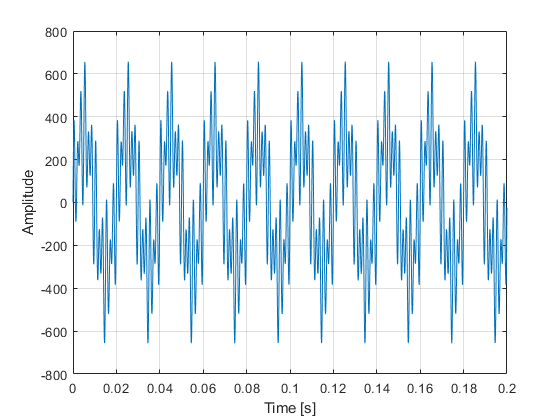


f1=50;
A1= 325;

f2= 600;
A2= 200;

f3= 400;
A3= 150;

Sig1 = A1*sin(2*pi*f1*t);
Sig2 = A2*sin(2*pi*f2*t);
Sig3 = A3*sin(2*pi*f3*t);
Final=Sig1+Sig2+Sig3;
plot(t,Final)
grid;
xlabel('Time [s]');
ylabel ('Amplitude');

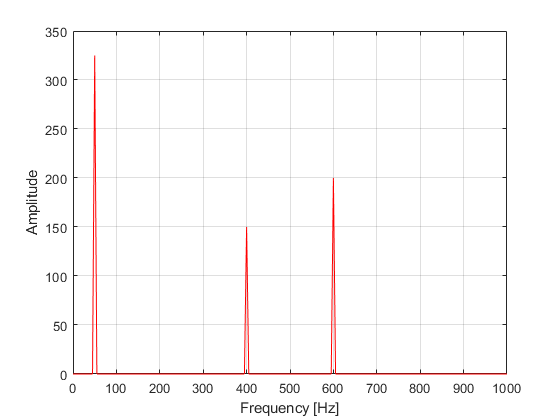


% FFT  
Y = fft(Final);
f = Fs*(0:(L/2))/L;
P = abs(Y/L);
plot(f,2*P(1:L/2+1),'-r')
axis([0 1000 0 350])
grid
xlabel('Frequency [Hz]')
ylabel('Amplitude')

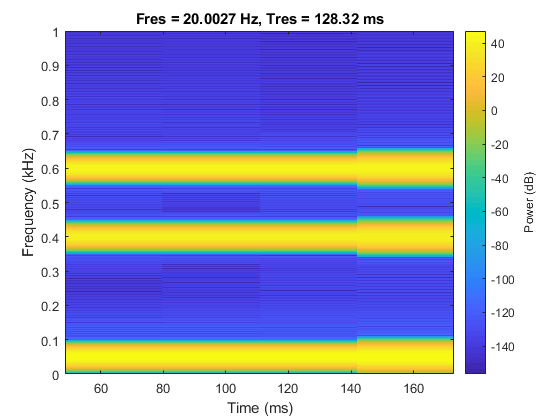


pspectrum(Final,Fs,'spectrogram','FrequencyLimits',[0 1000],'FrequencyResolution',20)